folder = fileparts(which('C:\Users\User\OneDrive\Documents\githubProjects\PE_Omission-Anat\eeglab2023.0\functions')); 
addpath(genpath(folder));

## Use of Anat's code to extract and preprocess orig data for Sleep Events (ss & kcomp) detection

******************************************************


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\User\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.7.9 to the path - new version 3.8.1 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 5.1 available
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)


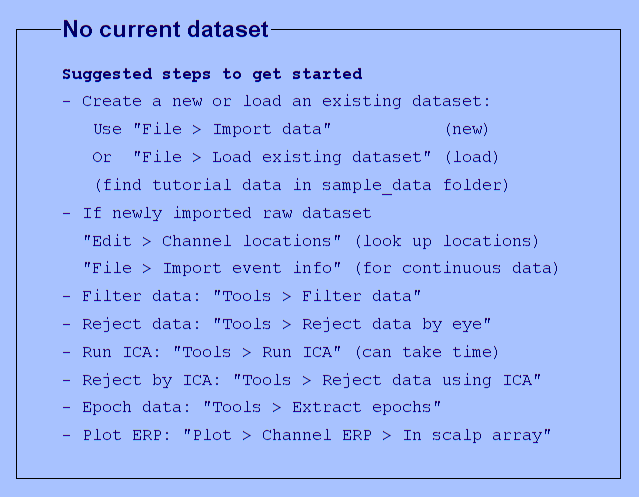

You are using the latest version of EEGLAB.


import_type ='eventDetectionChan';
preproc_name =  'imported';

input_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\';
output_dir = strcat('C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\',preproc_name,'_',import_type,'\no_filters\');


electrodesNames =     { 'E9','E22','E36','E104','E70','E83','E24','E124','E52','E92','Cz'}; 
electrodesEvenDetection_names = {'Fp1','Fp2','C3','C4','O1', 'O2','F3',  'F4', 'P3', 'P4', 'Cz'};

subs = {'01','02','03','04','05','06','07','08','09','10','11','12','13','14','15','16','17','18','19','20','21','22','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};
[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

if ~isfolder(output_dir)
    mkdir(output_dir);
end

for sub_ind=1:size(subs,2)
    for sleepFileNum=1:6
        % run only if output file doesnt exists
        sleep_files_name_suffix = strcat('_sleep',num2str(sleepFileNum),'_',preproc_name,'.set');
        output_filename = strcat('sub',subs(sub_ind),'_sleep',num2str(sleepFileNum),'_', preproc_name, '_',import_type);
        output_filename = output_filename{1};
        if isfile([output_dir output_filename '.mat'])
            string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  output_filename))
            continue
        end
        
        % upload .set file
        set_filename = strcat('s_',subs(sub_ind),'_sleep',num2str(sleepFileNum),'_orig.set');
        set_filename = set_filename{1};
        if ~isfile([input_dir '\' set_filename])
            ['no input file ' input_dir set_filename]
            continue
        end
        try
            EEG =  pop_loadset(set_filename, input_dir);
            [ALLEEG, EEG, CURRENTSET] = eeg_store( ALLEEG, EEG, 0 );
            EEG = eeg_checkset(EEG);
        catch ME
            ['error uploading ' input_dir set_filename]
            continue
        end 

        % reref to mastoid
        EEG = rereferenceFullNightSleep(EEG,3); %3 = linked mastoid
            
        % get labels and change thire names 
        all_labels = {EEG.chanlocs.labels};
        electrodesNumber =[];
        for label_ind=1:size(all_labels,2)
            if any(ismember(electrodesNames, all_labels(label_ind)))
                electrodesNumber(end+1) = label_ind;
            end
        end
        if size(electrodesNames,2) > size(electrodesNumber,2) 
            'didnt find all electrodes labels' 
        end
        [EEG.chanlocs(1,electrodesNumber).labels] = deal(electrodesEvenDetection_names{:});
                    
        % exclude all electrode but the ones listed in loc
        chanexcl = 1:size(all_labels,2);
        chanexcl(electrodesNumber) = [];
        EEG = pop_select(EEG,'nochannel',chanexcl);
        
        %% savings
        % save .set
%         [ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off');
%         EEG = pop_saveset(EEG, 'filename',[output_filename],'filepath',output_dir);
%         % save .bdf
%         pop_writeeeg(EEG, [output_dir output_filename '.bdf'],'TYPE','BDF'); %% no other intersting parameters.

        % save .mat
        subEvents = EEG.event;
        subData = EEG.data;
        samplefreq = EEG.srate;
        chansNames  = electrodesEvenDetection_names;
        save([output_dir, output_filename '.mat'],"subEvents","subData","samplefreq",'chansNames');
    end
end

ans = "Sub_01 already exists in path:sub01_sleep1_imported_eventDetectionChan"

ans = "Sub_01 already exists in path:sub01_sleep2_imported_eventDetectionChan"

ans = "Sub_01 already exists in path:sub01_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_01_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_01_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_01_sleep6_orig.set'

ans = "Sub_02 already exists in path:sub02_sleep1_imported_eventDetectionChan"

ans = "Sub_02 already exists in path:sub02_sleep2_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_02_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_02_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_02_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_02_sleep6_orig.set'

ans = "Sub_03 already exists in path:sub03_sleep1_imported_eventDetectionChan"

ans = "Sub_03 already exists in path:sub03_sleep2_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_03_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_03_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_03_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_03_sleep6_orig.set'

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep1_orig.set ...


Creating a new ALLEEG dataset 1


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep2_orig.set ...


Creating a new ALLEEG dataset 2


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep6_orig.set'

ans = "Sub_05 already exists in path:sub05_sleep1_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_05_sleep2_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_05_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_05_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_05_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_05_sleep6_orig.set'

ans = "Sub_06 already exists in path:sub06_sleep1_imported_eventDetectionChan"

ans = "Sub_06 already exists in path:sub06_sleep2_imported_eventDetectionChan"

ans = "Sub_06 already exists in path:sub06_sleep3_imported_eventDetectionChan"

ans = "Sub_06 already exists in path:sub06_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_06_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_06_sleep6_orig.set'

ans = "Sub_07 already exists in path:sub07_sleep1_imported_eventDetectionChan"

ans = "Sub_07 already exists in path:sub07_sleep2_imported_eventDetectionChan"

ans = "Sub_07 already exists in path:sub07_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_07_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_07_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_07_sleep6_orig.set'

ans = "Sub_08 already exists in path:sub08_sleep1_imported_eventDetectionChan"

ans = "Sub_08 already exists in path:sub08_sleep2_imported_eventDetectionChan"

ans = "Sub_08 already exists in path:sub08_sleep3_imported_eventDetectionChan"

ans = "Sub_08 already exists in path:sub08_sleep4_imported_eventDetectionChan"

ans = "Sub_08 already exists in path:sub08_sleep5_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_08_sleep6_orig.set'

ans = "Sub_09 already exists in path:sub09_sleep1_imported_eventDetectionChan"

ans = "Sub_09 already exists in path:sub09_sleep2_imported_eventDetectionChan"

ans = "Sub_09 already exists in path:sub09_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_09_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_09_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_09_sleep6_orig.set'

ans = "Sub_10 already exists in path:sub10_sleep1_imported_eventDetectionChan"

ans = "Sub_10 already exists in path:sub10_sleep2_imported_eventDetectionChan"

ans = "Sub_10 already exists in path:sub10_sleep3_imported_eventDetectionChan"

ans = "Sub_10 already exists in path:sub10_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_10_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_10_sleep6_orig.set'

ans = "Sub_11 already exists in path:sub11_sleep1_imported_eventDetectionChan"

ans = "Sub_11 already exists in path:sub11_sleep2_imported_eventDetectionChan"

ans = "Sub_11 already exists in path:sub11_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_11_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_11_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_11_sleep6_orig.set'

ans = "Sub_12 already exists in path:sub12_sleep1_imported_eventDetectionChan"

ans = "Sub_12 already exists in path:sub12_sleep2_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_12_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_12_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_12_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_12_sleep6_orig.set'

ans = "Sub_13 already exists in path:sub13_sleep1_imported_eventDetectionChan"

ans = "Sub_13 already exists in path:sub13_sleep2_imported_eventDetectionChan"

ans = "Sub_13 already exists in path:sub13_sleep3_imported_eventDetectionChan"

ans = "Sub_13 already exists in path:sub13_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_13_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_13_sleep6_orig.set'

ans = "Sub_14 already exists in path:sub14_sleep1_imported_eventDetectionChan"

ans = "Sub_14 already exists in path:sub14_sleep2_imported_eventDetectionChan"

ans = "Sub_14 already exists in path:sub14_sleep3_imported_eventDetectionChan"

ans = "Sub_14 already exists in path:sub14_sleep4_imported_eventDetectionChan"

ans = "Sub_14 already exists in path:sub14_sleep5_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_14_sleep6_orig.set'

ans = "Sub_15 already exists in path:sub15_sleep1_imported_eventDetectionChan"

ans = "Sub_15 already exists in path:sub15_sleep2_imported_eventDetectionChan"

ans = "Sub_15 already exists in path:sub15_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_15_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_15_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_15_sleep6_orig.set'

ans = "Sub_16 already exists in path:sub16_sleep1_imported_eventDetectionChan"

ans = "Sub_16 already exists in path:sub16_sleep2_imported_eventDetectionChan"

ans = "Sub_16 already exists in path:sub16_sleep3_imported_eventDetectionChan"

ans = "Sub_16 already exists in path:sub16_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_16_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_16_sleep6_orig.set'

ans = "Sub_17 already exists in path:sub17_sleep1_imported_eventDetectionChan"

ans = "Sub_17 already exists in path:sub17_sleep2_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_17_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_17_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_17_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_17_sleep6_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_18_sleep1_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_18_sleep2_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_18_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_18_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_18_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_18_sleep6_orig.set'

ans = "Sub_19 already exists in path:sub19_sleep1_imported_eventDetectionChan"

ans = "Sub_19 already exists in path:sub19_sleep2_imported_eventDetectionChan"

ans = "Sub_19 already exists in path:sub19_sleep3_imported_eventDetectionChan"

ans = "Sub_19 already exists in path:sub19_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_19_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_19_sleep6_orig.set'

ans = "Sub_20 already exists in path:sub20_sleep1_imported_eventDetectionChan"

ans = "Sub_20 already exists in path:sub20_sleep2_imported_eventDetectionChan"

ans = "Sub_20 already exists in path:sub20_sleep3_imported_eventDetectionChan"

ans = "Sub_20 already exists in path:sub20_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_20_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_20_sleep6_orig.set'

ans = "Sub_21 already exists in path:sub21_sleep1_imported_eventDetectionChan"

ans = "Sub_21 already exists in path:sub21_sleep2_imported_eventDetectionChan"

ans = "Sub_21 already exists in path:sub21_sleep3_imported_eventDetectionChan"

ans = "Sub_21 already exists in path:sub21_sleep4_imported_eventDetectionChan"

ans = "Sub_21 already exists in path:sub21_sleep5_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_21_sleep6_orig.set'

ans = "Sub_22 already exists in path:sub22_sleep1_imported_eventDetectionChan"

ans = "Sub_22 already exists in path:sub22_sleep2_imported_eventDetectionChan"

ans = "Sub_22 already exists in path:sub22_sleep3_imported_eventDetectionChan"

ans = "Sub_22 already exists in path:sub22_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_22_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_22_sleep6_orig.set'

ans = "Sub_23 already exists in path:sub23_sleep1_imported_eventDetectionChan"

ans = "Sub_23 already exists in path:sub23_sleep2_imported_eventDetectionChan"

ans = "Sub_23 already exists in path:sub23_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_23_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_23_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_23_sleep6_orig.set'

ans = "Sub_24 already exists in path:sub24_sleep1_imported_eventDetectionChan"

ans = "Sub_24 already exists in path:sub24_sleep2_imported_eventDetectionChan"

ans = "Sub_24 already exists in path:sub24_sleep3_imported_eventDetectionChan"

ans = "Sub_24 already exists in path:sub24_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_24_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_24_sleep6_orig.set'

ans = "Sub_25 already exists in path:sub25_sleep1_imported_eventDetectionChan"

ans = "Sub_25 already exists in path:sub25_sleep2_imported_eventDetectionChan"

ans = "Sub_25 already exists in path:sub25_sleep3_imported_eventDetectionChan"

ans = "Sub_25 already exists in path:sub25_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_25_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_25_sleep6_orig.set'

ans = "Sub_26 already exists in path:sub26_sleep1_imported_eventDetectionChan"

ans = "Sub_26 already exists in path:sub26_sleep2_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_26_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_26_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_26_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_26_sleep6_orig.set'

ans = "Sub_27 already exists in path:sub27_sleep1_imported_eventDetectionChan"

ans = "Sub_27 already exists in path:sub27_sleep2_imported_eventDetectionChan"

ans = "Sub_27 already exists in path:sub27_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_27_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_27_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_27_sleep6_orig.set'

ans = "Sub_28 already exists in path:sub28_sleep1_imported_eventDetectionChan"

ans = "Sub_28 already exists in path:sub28_sleep2_imported_eventDetectionChan"

ans = "Sub_28 already exists in path:sub28_sleep3_imported_eventDetectionChan"

ans = "Sub_28 already exists in path:sub28_sleep4_imported_eventDetectionChan"

ans = "Sub_28 already exists in path:sub28_sleep5_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_28_sleep6_orig.set'

ans = "Sub_29 already exists in path:sub29_sleep1_imported_eventDetectionChan"

ans = "Sub_29 already exists in path:sub29_sleep2_imported_eventDetectionChan"

ans = "Sub_29 already exists in path:sub29_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_29_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_29_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_29_sleep6_orig.set'

ans = "Sub_30 already exists in path:sub30_sleep1_imported_eventDetectionChan"

ans = "Sub_30 already exists in path:sub30_sleep2_imported_eventDetectionChan"

ans = "Sub_30 already exists in path:sub30_sleep3_imported_eventDetectionChan"

ans = "Sub_30 already exists in path:sub30_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_30_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_30_sleep6_orig.set'

ans = "Sub_31 already exists in path:sub31_sleep1_imported_eventDetectionChan"

ans = "Sub_31 already exists in path:sub31_sleep2_imported_eventDetectionChan"

ans = "Sub_31 already exists in path:sub31_sleep3_imported_eventDetectionChan"

ans = "Sub_31 already exists in path:sub31_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_31_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_31_sleep6_orig.set'

ans = "Sub_32 already exists in path:sub32_sleep1_imported_eventDetectionChan"

ans = "Sub_32 already exists in path:sub32_sleep2_imported_eventDetectionChan"

ans = "Sub_32 already exists in path:sub32_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_32_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_32_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_32_sleep6_orig.set'

ans = "Sub_33 already exists in path:sub33_sleep1_imported_eventDetectionChan"

ans = "Sub_33 already exists in path:sub33_sleep2_imported_eventDetectionChan"

ans = "Sub_33 already exists in path:sub33_sleep3_imported_eventDetectionChan"

ans = "Sub_33 already exists in path:sub33_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_33_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_33_sleep6_orig.set'

ans = "Sub_34 already exists in path:sub34_sleep1_imported_eventDetectionChan"

ans = "Sub_34 already exists in path:sub34_sleep2_imported_eventDetectionChan"

ans = "Sub_34 already exists in path:sub34_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_34_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_34_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_34_sleep6_orig.set'

ans = "Sub_35 already exists in path:sub35_sleep1_imported_eventDetectionChan"

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_35_sleep2_orig.set ...


ans = 'error uploading C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_35_sleep2_orig.set'

ans = "Sub_35 already exists in path:sub35_sleep3_imported_eventDetectionChan"

ans = "Sub_35 already exists in path:sub35_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_35_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_35_sleep6_orig.set'

ans = "Sub_36 already exists in path:sub36_sleep1_imported_eventDetectionChan"

ans = "Sub_36 already exists in path:sub36_sleep2_imported_eventDetectionChan"

ans = "Sub_36 already exists in path:sub36_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_36_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_36_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_36_sleep6_orig.set'

ans = "Sub_37 already exists in path:sub37_sleep1_imported_eventDetectionChan"

ans = "Sub_37 already exists in path:sub37_sleep2_imported_eventDetectionChan"

ans = "Sub_37 already exists in path:sub37_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_37_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_37_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_37_sleep6_orig.set'

ans = "Sub_38 already exists in path:sub38_sleep1_imported_eventDetectionChan"

ans = "Sub_38 already exists in path:sub38_sleep2_imported_eventDetectionChan"

ans = "Sub_38 already exists in path:sub38_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_38_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_38_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_38_sleep6_orig.set'